# Proyecto Final

Obtiene todas las imágenes de cada clase del directorio *Objetos_segmentados*

[imageClasses,labelMap] = ImageProcessing.getImagesClasses("Objetos_segmentados");

Se muestra la imagen 8 de la séptima clase

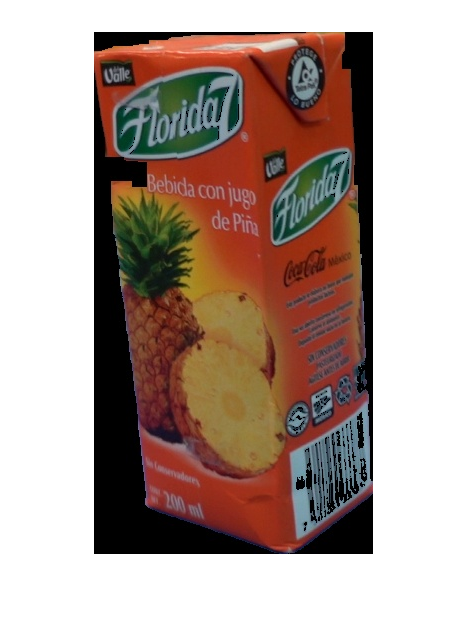

imshow(imageClasses{7}{8})

Se muestran las propiedades de labelMap y un ejemplo de su uso

labelMap

labelMap =   Map with properties:

        Count: 10
      KeyType: double
    ValueType: char


fprintf('A la clase %d le pertence la etiqueta %s',1,labelMap(1));

A la clase 1 le pertence la etiqueta appleJuice

Divide a las imágenes en datos de entreneamiento y datos de prueba

images_train = cellfun(@(imageClass) imageClass(1:15), imageClasses, 'UniformOutput', false);
images_test = cellfun(@(imageClass) imageClass(16:end), imageClasses, 'UniformOutput', false);

Obtiene los canales RGB de la muestra 8 de la clase 7 para desplegarlos

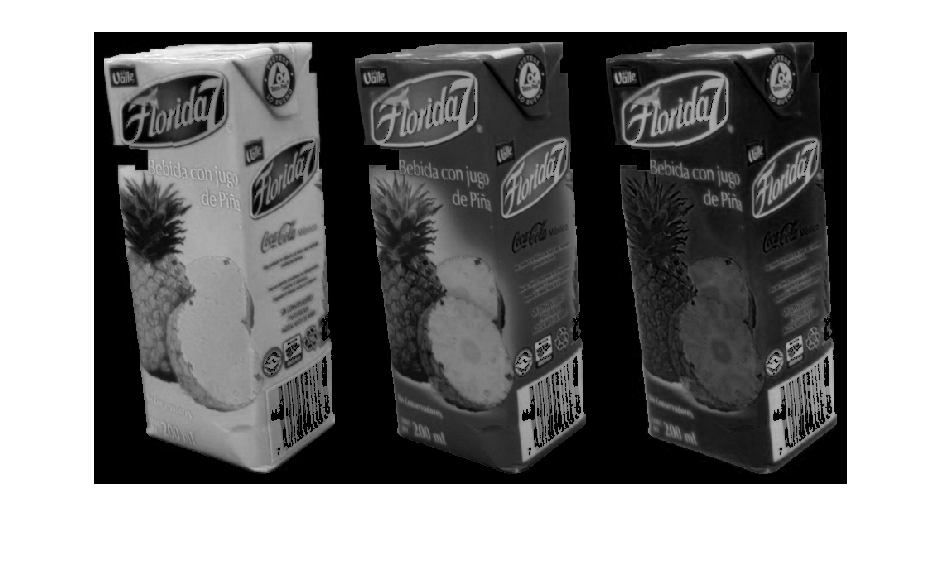

[r g b] = imsplit(images_train{7}{8});
montage({r, g, b}, 'BorderSize', 10);

Despliegue de la imagen aplicando filtros de sobel horizontales

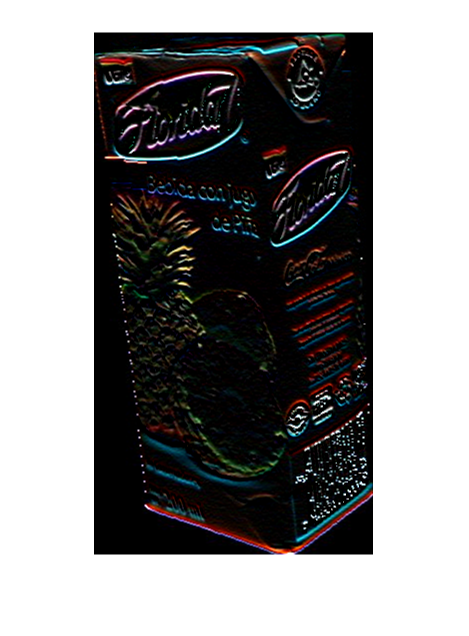

test = ImageProcessing.filter(images_train{7}{8});
img = cat(3,test(:,:,7),test(:,:,8),test(:,:,9));
imshow(img)

Para cada clase de imagenes se obtiene su cuantizador vectorial

sizeQuantizer = 16; % Tamaño de los cuantizadores vectoriales
vecQuantizers = {}; % Cell array para almacenar a los cuantizadores vectoriales
for i = 1:length(images_train)
  images_scaled = cellfun(@(image) imresize(image,0.5), images_train{i}, 'UniformOutput', false );
  images_filtered = cellfun(@ImageProcessing.filter, images_scaled, 'UniformOutput', false);
  pixels = ImageProcessing.imgClass2matrix(images_filtered);
  C1 = 1/length(pixels) *sum(pixels);
  [idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,sizeQuantizer,double(pixels));
  vecQuantizers{i} = {idx, C};
end

Se verifican los centroides obtenidos, así como la cantidad de elementos que contiene cada grupo en el cuantizador vectorial de la clase appleJuice.

idx_1 = vecQuantizers{1}{1}; %Índices asignados a cada pixel de la clase appleJuice
C_1 = vecQuantizers{1}{2} %Centroides del cuantizador de la clase appleJuice

C_1 =

    1.4215    0.7092    1.0123    2.6502    1.6333    2.0073    1.9782    1.5759    2.4865
   51.0194  101.9546   82.9357   12.5119    8.5557    7.8185    8.7042    6.3611    6.1644
   85.0413   28.0240   37.3344   12.6299   10.4229    8.3711    9.7674    8.1770    6.1130
  100.7279   92.9595   92.9664   17.5157   22.8650   21.7366  193.7619  239.1162  240.1377
   91.3015   63.4121   65.4475   56.0590  137.6764  117.8832   15.5684   20.9426   17.4191
  105.7211  125.3205  124.5813    9.0470    6.7440    7.3341    6.3045    4.5253    4.8877
   89.5772   71.8226   70.4841   15.7049   24.1711   20.0445   51.8060  183.1568  154.4149
   46.8808   41.1958   41.9473  222.7613  202.2806  216.5473   19.0992   15.9179   17.1728
   78.7356   40.1422   45.7182   19.5554   12.5816   11.9098  107.4945   53.2155   51.0993
  118.3377  130.2442  127.7684   13.0925   10.6094   11.6117   73.4255   66.4534   76.0308
  123.5340   67.8537   67.0446   12.9565   13.0143   10.9605    9.6005   12.6020   

for i=1:sizeQuantizer
  fprintf('Centroide: %d  Elementos: %d\n',i,numel(find(idx_1 == i)))
end

Centroide: 1  Elementos: 44680
Centroide: 2  Elementos: 18160
Centroide: 3  Elementos: 43613
Centroide: 4  Elementos: 9614
Centroide: 5  Elementos: 13767
Centroide: 6  Elementos: 33116
Centroide: 7  Elementos: 9422
Centroide: 8  Elementos: 6283
Centroide: 9  Elementos: 13288
Centroide: 10  Elementos: 13971
Centroide: 11  Elementos: 22732
Centroide: 12  Elementos: 5807
Centroide: 13  Elementos: 11823
Centroide: 14  Elementos: 38495
Centroide: 15  Elementos: 7850
Centroide: 16  Elementos: 9708


Clasificación de las imagenes de entrenamiento

disp('Clasificando las imágenes de entrenamiento')

Clasificando las imágenes de entrenamiento


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3     3     3     3     3     2     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     2     5     2     2     5     5     5     5     5     5     5     5     5     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6

La clasificación para las imágenes de la clase 7

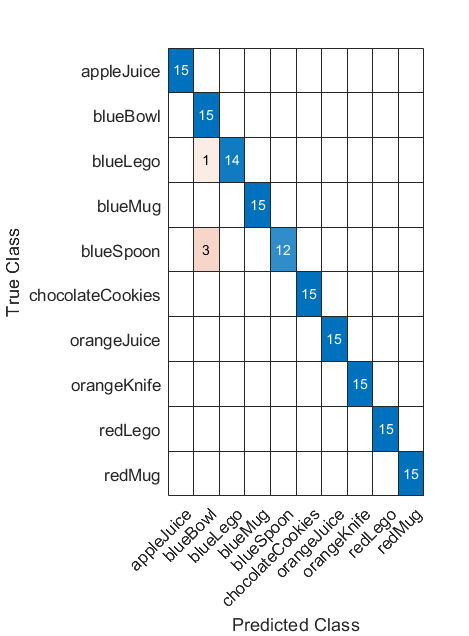

clasificacionCuantVect(images_train,vecQuantizers,labelMap)

Clasificación de las imagenes de prueba

disp('Clasificando las imágenes de prueba')

Clasificando las imágenes de prueba


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     5     5     5     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6

La clasificación para las imágenes de la clase 7 (orangeJuice) fue:
     7     7     7     7     7

La clasificación para las imágenes de la clase 8 (orangeKnife) fue:
     8     8     8     8     8

La clasificación para las imágenes de la clase 9 (redLego) fue:
     9     9     9     9     9

La clasificación para las imágenes de la clase 10 (redMug) fue:
    10     9    10    10    10



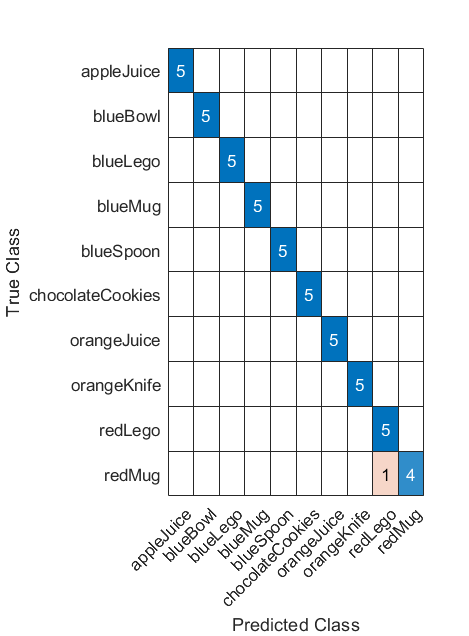

clasificacionCuantVect(images_test,vecQuantizers,labelMap)

**Clasificación de imágenes mediante cuantización vectorial**

Función para clasificar las imagenes, ya sea de entrenamiento o de prueba mediante la tecnica de cuantización vectorial.

Al final muestra su matriz de confusión.

function clasificacionCuantVect(imgClass,quantizers,labelMap)
  prediction = double.empty; % Valores que el clasificador predice
  actual = double.empty; % Valores reales
  
  for i=1:length(imgClass) % Itera sobre las clases
    nImgs = length(imgClass{i});
    clasifications = zeros(1,nImgs);
    for j=1:nImgs % Itera sobre las imágenes de la clase iésima
      % Obtiene los pixeles de la imagen
      image_scaled = imresize(imgClass{i}{j},0.5);
      image_filtered = ImageProcessing.filter(image_scaled);
      pixels = ImageProcessing.img2matrix(image_filtered);
      % Obtiene la clasificación de la imagen de acuerdo a su distancia
      % mínima a cada cuantizador
      clasifications(j) = CuantizadorVectorial.clasificador(double(pixels),quantizers);
    end
    prediction = [prediction,clasifications];
    actual = [actual,ones(1,nImgs)*i];
    fprintf('La clasificación para las imágenes de la clase %d (%s) fue:\n',i,labelMap(i));
    disp(clasifications)
  end
  
  
  % Obtiene las etiquetas de los valores reales y predichos
  labelActual = arrayfun(@(num) labelMap(num),actual,'UniformOutput',false);
  labelPred = arrayfun(@(num) labelMap(num),prediction,'UniformOutput',false);
  % Genera una matriz de confusión y las muestra
  confusionchart(labelActual,labelPred)
end